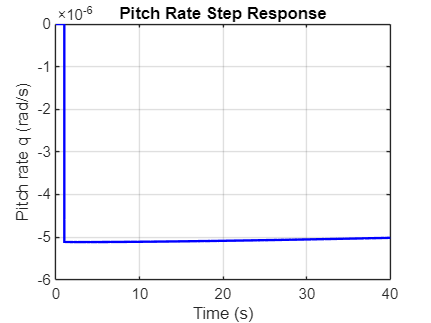

clear
clc


% 0 Controller value

Kp_1 = 977;

% 1 Run model
open('Pitch_Rate_Damper.slx')
out = sim('Pitch_Rate_Damper.slx');

% 2 Extract time and signal data
t = out.q.Time;      % Time vector
q = out.q.Data;      % Pitch rate (rad/s)

% 3 Compute step response characteristics

% Plot for verification
figure;
plot(t, q, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Pitch rate q (rad/s)');
title('Pitch Rate Step Response');
grid on;


% Compute step response characteristics
info = stepinfo(q, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 1.4026e-04
    TransientTime: 2.9213
     SettlingTime: 2.9213
      SettlingMin: -5.1189e-06
      SettlingMax: -4.5884e-06
        Overshoot: 2.0390
       Undershoot: 0
             Peak: 5.1189e-06
         PeakTime: 1.0009

